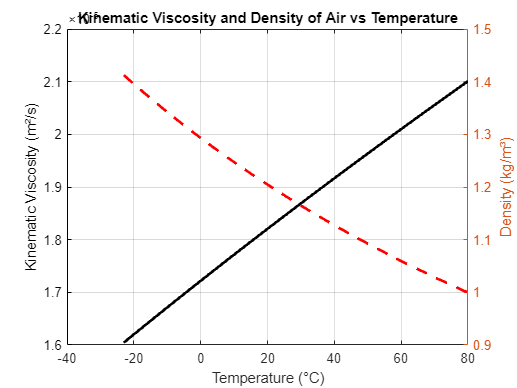


% Define the temperature range in Kelvin
T = 273.15 + (-23:80);  % Temperature from 0°C to 100°C

% Calculate kinematic viscosity for air at each temperature
KinVisc_T = arrayfun(@(temp) py.CoolProp.CoolProp.PropsSI('V', 'T', temp, 'P', 101325, 'Air'), T);
rho_air = arrayfun(@(temp) py.CoolProp.CoolProp.PropsSI('D', 'T', temp, 'P', 101325, 'Air'), T);

% Plotting kinematic viscosity vs temperature
figure;
plot(T - 273.15, KinVisc_T, 'k-', 'LineWidth', 2);  % Temperature in °C
xlabel('Temperature (°C)');
ylabel('Kinematic Viscosity (m²/s)');
title('Kinematic Viscosity and Density of Air vs Temperature');
grid on;

% Right y-axis: Density
yyaxis right;
plot(T - 273.15, rho_air, 'r--', 'LineWidth', 2);  % Temperature in °C
ylabel('Density (kg/m³)');

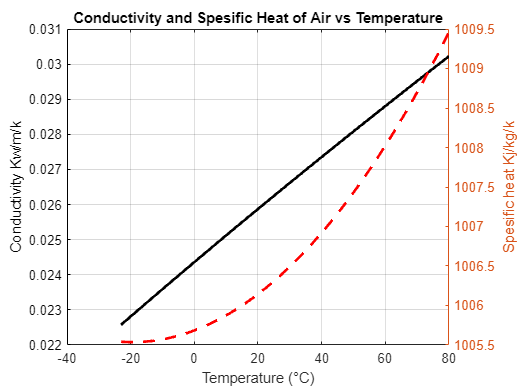



% Calculate kinematic viscosity for air at each temperature
Kair = arrayfun(@(temp) py.CoolProp.CoolProp.PropsSI('L', 'T', temp, 'P', 101325, 'Air'), T);
heatCapAir = arrayfun(@(temp) py.CoolProp.CoolProp.PropsSI('Cpmass', 'T', temp, 'P', 101325, 'Air'), T);

% Plotting kinematic viscosity vs temperature
figure;
plot(T - 273.15, Kair, 'k-', 'LineWidth', 2);  % Temperature in °C
xlabel('Temperature (°C)');
ylabel('Conductivity Kw/m/k');
title('Conductivity and Spesific Heat of Air vs Temperature');
grid on;

% Right y-axis: Density
yyaxis right;
plot(T - 273.15, heatCapAir, 'r--', 'LineWidth', 2);  % Temperature in °C
ylabel('Spesific heat Kj/kg/k');



%Plotting deviation from room temperature
BaseTemp = 23 + 273.15;
BaselineKinVisc_T = py.CoolProp.CoolProp.PropsSI('V', 'T', BaseTemp, 'P', 101325, 'Air')

BaselineKinVisc_T = 1.8351e-05

BaselineRho = py.CoolProp.CoolProp.PropsSI('D', 'T', BaseTemp, 'P', 101325, 'Air')

BaselineRho = 1.1923

BaselineKcond = py.CoolProp.CoolProp.PropsSI('L', 'T', BaseTemp, 'P', 101325, 'Air')

BaselineKcond = 0.0261

BaselineCpmass = py.CoolProp.CoolProp.PropsSI('Cpmass', 'T', BaseTemp, 'P', 101325, 'Air')

BaselineCpmass = 1.0062e+03

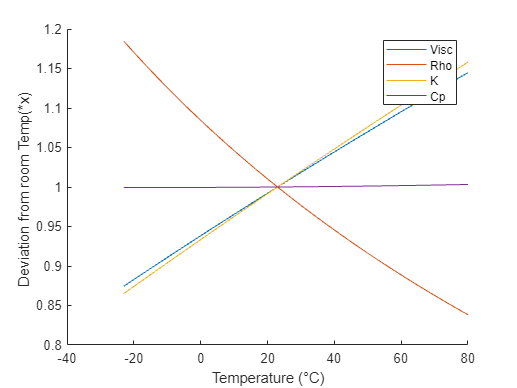


devKinVisc = KinVisc_T/BaselineKinVisc_T;
devRho = rho_air/BaselineRho;
devKcond = Kair/BaselineKcond;
devCpmass = heatCapAir/BaselineCpmass;

figure;
hold on;
plot(T-273.15,devKinVisc,'DisplayName','Visc')
legend()
plot(T-273.15,devRho,"DisplayName","Rho")
plot(T-273.15,devKcond,"DisplayName","K")
plot(T-273.15,devCpmass,"DisplayName","Cp");
xlabel("Temperature (°C)")
ylabel("Deviation from room Temp(*x) ")
hold off

Lets input an example to see how much this change in properties will have on the nusselt number. 

This represents cylinder in cross flow